clear all
load('predicted_total_number_to_2040.mat')
load('survival_number_and_rates.mat')

% a small number
epsilon=0;

fileName = 'fyy1.xlsx';
sheetName='Sheet2';
data_all = readtable(fileName, 'Sheet', sheetName);

car_BE=data_all(strcmp(data_all.BodyType,'Cars')...
    &strcmp(data_all.Fuel,'Battery electric'),4:end-2);
LGV_BE=data_all(strcmp(data_all.BodyType,'Light goods vehicles')...
    &strcmp(data_all.Fuel,'Battery electric'),4:end-2);
[car_BE_remain_number_year,car_BE_remain_rate_age]=get_survival_rate_matridatac(car_BE);
[LGV_BE_remain_number_year,LGV_BE_remain_rate_age]=get_survival_rate_matridatac(LGV_BE);

% Calculate the size of Matrix 
all_years=1994:2040;
predict_years=2024:2040;
all_years_num=length(all_years);
predict_years_num=length(predict_years);
years_col_num=size(All_remain_number_year_data,2);
years_raw_num=size(All_remain_number_year_data,1);

### Car

% Set up matrix
all_car_diesel=nan(all_years_num,predict_years_num+years_col_num);
all_car_petrol=nan(all_years_num,predict_years_num+years_col_num);
all_car_BE=nan(all_years_num,predict_years_num+years_col_num);

all_car_diesel(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,1);
all_car_petrol(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,5);
all_car_BE(1:years_raw_num,predict_years_num+1:end)=car_BE_remain_number_year;


car_diesel_mid_rate=mid_survival_rate(:,1);
car_petrol_mid_rate=mid_survival_rate(:,5);
% car_BE_register_rate=[0.22;0.28;0.33;0.38;0.52;0.66;0.80;0.84;0.88;0.92;0.96;1;1;1;1;1;1];
car_BE_register_rate=[0.25;0.28;0.32;0.36;0.47;0.62;0.77;0.88;0.95;0.98;0.99;1.;1;1;1;1;1];
[all_car_diesel,all_car_petrol,all_car_BE]=fulfil_car_LGV_all(future_car,all_car_diesel,all_car_petrol,all_car_BE,car_diesel_mid_rate,car_petrol_mid_rate, ...
    car_BE_register_rate,predict_years_num,years_col_num,years_raw_num,epsilon);

Best ARIMA Model: ARIMA(3,1,3)
Best AIC: -188.1259
Best ARIMA Model: ARIMA(3,2,2)
Best AIC: -202.7553
Best ARIMA Model: ARIMA(2,0,1)
Best AIC: -143.4551


### LGV

% Set up matrix
all_LGV_diesel=nan(all_years_num,predict_years_num+years_col_num);
all_LGV_petrol=nan(all_years_num,predict_years_num+years_col_num);
all_LGV_BE=nan(all_years_num,predict_years_num+years_col_num);

all_LGV_diesel(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,2);
all_LGV_petrol(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,6);
all_LGV_BE(1:years_raw_num,predict_years_num+1:end)=LGV_BE_remain_number_year;

% Step 1: soomth rate 预测补全至0 
LGV_diesel_mid_rate=mid_survival_rate(:,1);
LGV_petrol_mid_rate=mid_survival_rate(:,5);
LGV_BE_register_rate=[0.09;0.12;0.17;0.21;0.35;0.53;0.72;0.85;0.93;0.97;0.99;1;1;1;1;1;1];
[all_LGV_diesel,all_LGV_petrol,all_LGV_BE]=fulfil_car_LGV_all(future_LGV,all_LGV_diesel,all_LGV_petrol,all_LGV_BE,LGV_diesel_mid_rate,LGV_petrol_mid_rate, ...
    LGV_BE_register_rate,predict_years_num,years_col_num,years_raw_num,epsilon);

Best ARIMA Model: ARIMA(3,1,3)
Best AIC: -188.1259
Best ARIMA Model: ARIMA(3,2,2)
Best AIC: -202.7553
Best ARIMA Model: ARIMA(3,0,2)
Best AIC: -239.9973


### bus (sheet=3)

% Set up matrix
all_bus=nan(all_years_num,predict_years_num+years_col_num);

all_bus(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,3);

% Step 1: soomth rate 预测补全至0 
bus_mid_rate=mid_survival_rate(:,3);


all_bus=fulfil_total_all(future_bus,all_bus,bus_mid_rate, ...
    predict_years_num,years_col_num,years_raw_num,epsilon);

Best ARIMA Model: ARIMA(3,2,2)
Best AIC: -234.3757


### HGV (sheet=4)

% Set up matrix
all_HGV=nan(all_years_num,predict_years_num+years_col_num);

all_HGV(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,4);

% Step 1: soomth rate 预测补全至0 
HGV_mid_rate=mid_survival_rate(:,4);


all_HGV=fulfil_total_all(future_HGV,all_HGV,HGV_mid_rate, ...
    predict_years_num,years_col_num,years_raw_num,epsilon);

Best ARIMA Model: ARIMA(3,1,1)
Best AIC: -219.7325


### motor (sheet=7)

% Set up matrix
all_motor =nan(all_years_num,predict_years_num+years_col_num);

all_motor(1:years_raw_num,predict_years_num+1:end)=All_remain_number_year_data(:,:,7);

% Step 1: soomth rate 预测补全至0 
motor_mid_rate=mid_survival_rate(:,7);


all_motor=fulfil_total_all(future_motor,all_motor,motor_mid_rate, ...
    predict_years_num,years_col_num,years_raw_num,epsilon);

Best ARIMA Model: ARIMA(3,2,3)
Best AIC: -203.6338


% Draw the results

%figure: predicted the number in the market

% years=2024:2040;
% car_diesel_predict=sum(all_car_diesel(years_raw_num+1:end,:),2,"omitnan");
% car_petrol_predict=sum(all_car_petrol(years_raw_num+1:end,:),2,"omitnan");
% car_BE_predict=sum(all_car_BE(years_raw_num+1:end,:),2,"omitnan");
% LGV_diesel_predict=sum(all_LGV_diesel(years_raw_num+1:end,:),2,"omitnan");
% LGV_petrol_predict=sum(all_LGV_petrol(years_raw_num+1:end,:),2,"omitnan");
% LGV_BE_predict=sum(all_LGV_BE(years_raw_num+1:end,:),2,"omitnan");
% bus_predict=sum(all_bus(years_raw_num+1:end,:),2,"omitnan");
% HGV_predict=sum(all_HGV(years_raw_num+1:end,:),2,"omitnan");
% motor_predict=sum(all_motor(years_raw_num+1:end,:),2,"omitnan");

years=1994:2040;
car_diesel_predict=sum(all_car_diesel,2,"omitnan");
car_petrol_predict=sum(all_car_petrol,2,"omitnan");
car_BE_predict=sum(all_car_BE,2,"omitnan");
LGV_diesel_predict=sum(all_LGV_diesel,2,"omitnan");
LGV_petrol_predict=sum(all_LGV_petrol,2,"omitnan");
LGV_BE_predict=sum(all_LGV_BE,2,"omitnan");
bus_predict=sum(all_bus,2,"omitnan");
HGV_predict=sum(all_HGV,2,"omitnan");
motor_predict=sum(all_motor,2,"omitnan");

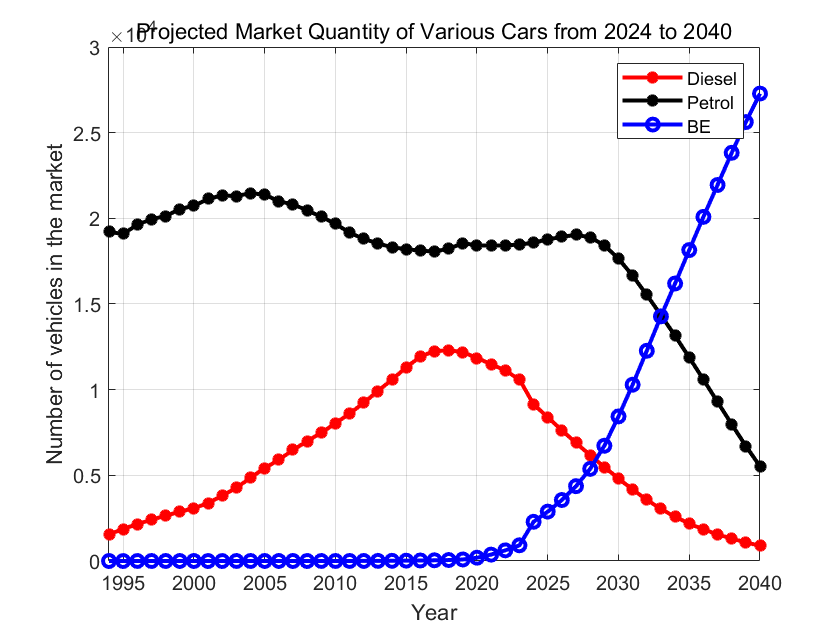


figure(1)
plot(years,car_diesel_predict,'-*r','LineWidth',2,"DisplayName",'Diesel')
hold on
plot(years,car_petrol_predict,'-*k','LineWidth',2,"DisplayName",'Petrol')
plot(years,car_BE_predict,'-ob','LineWidth',2,"DisplayName",'BE')
xlabel('Year');
ylabel('Number of vehicles in the market');
title('Projected Market Quantity of Various Cars from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

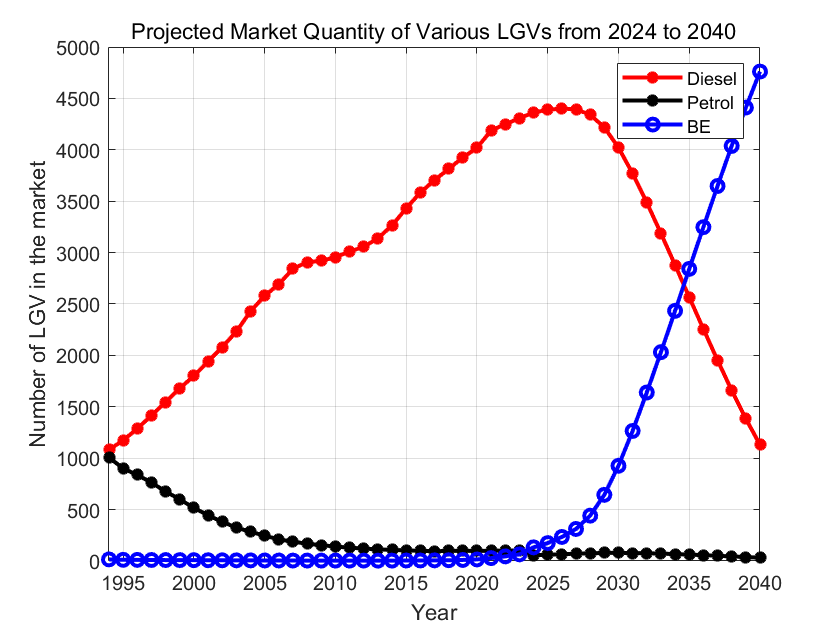


figure(2)
plot(years,LGV_diesel_predict,'-*r','LineWidth',2,"DisplayName",'Diesel')
hold on
plot(years,LGV_petrol_predict,'-*k','LineWidth',2,"DisplayName",'Petrol')
plot(years,LGV_BE_predict,'-ob','LineWidth',2,"DisplayName",'BE')
xlabel('Year');
ylabel('Number of LGV in the market');
title('Projected Market Quantity of Various LGVs from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

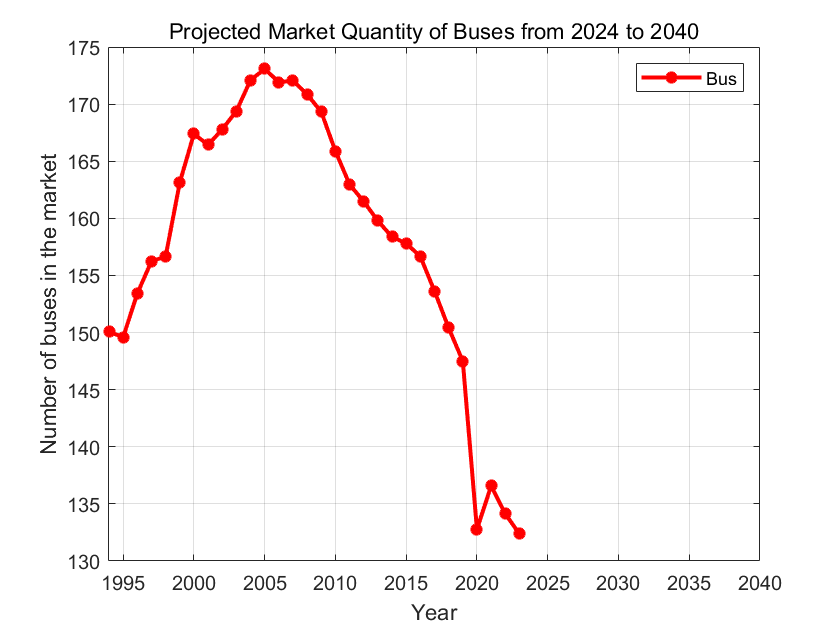


figure(3)
plot(years,bus_predict,'-*r','LineWidth',2,"DisplayName",'Bus')
hold on
xlabel('Year');
ylabel('Number of buses in the market');
title('Projected Market Quantity of Buses from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

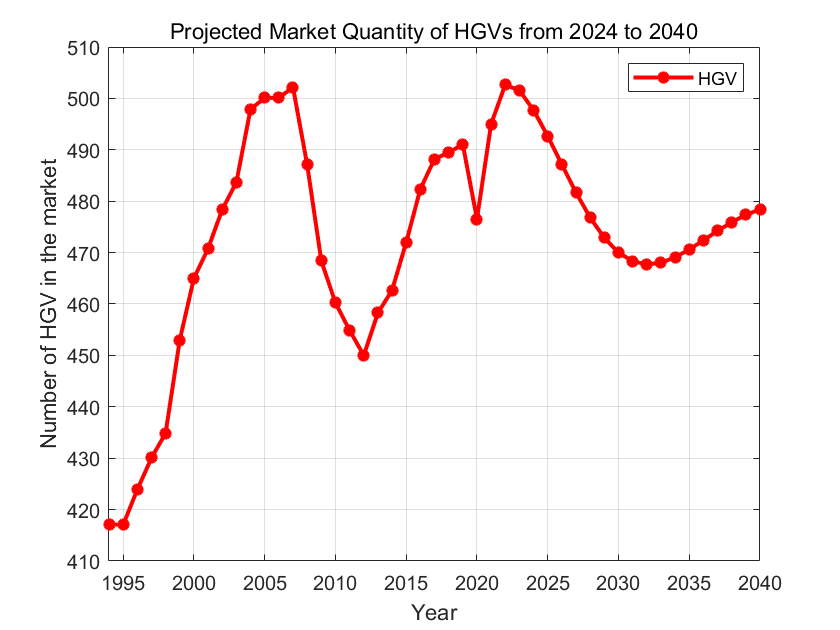


figure(4)
plot(years,HGV_predict,'-*r','LineWidth',2,"DisplayName",'HGV')
hold on
xlabel('Year');
ylabel('Number of HGV in the market');
title('Projected Market Quantity of HGVs from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

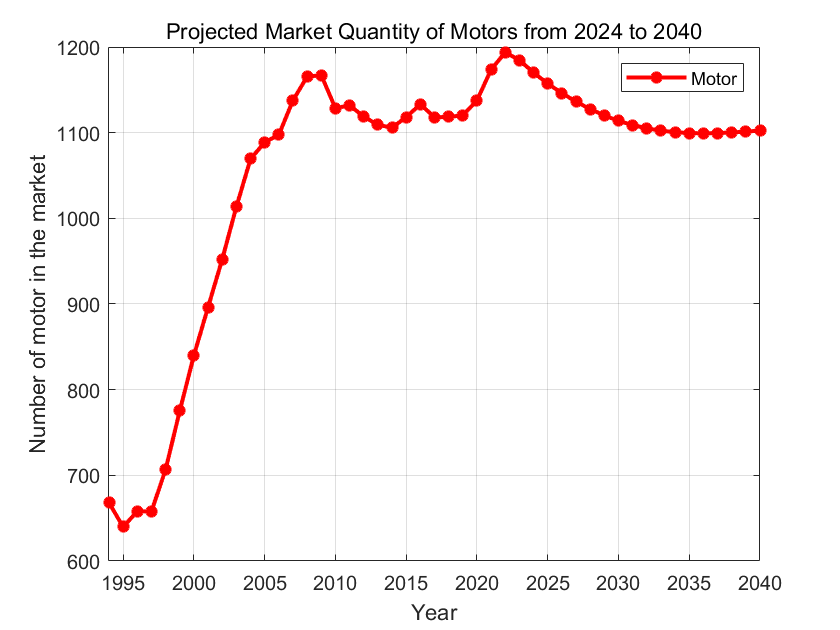


figure(5)
plot(years,motor_predict,'-*r','LineWidth',2,"DisplayName",'Motor')
hold on
xlabel('Year');
ylabel('Number of motor in the market');
title('Projected Market Quantity of Motors from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

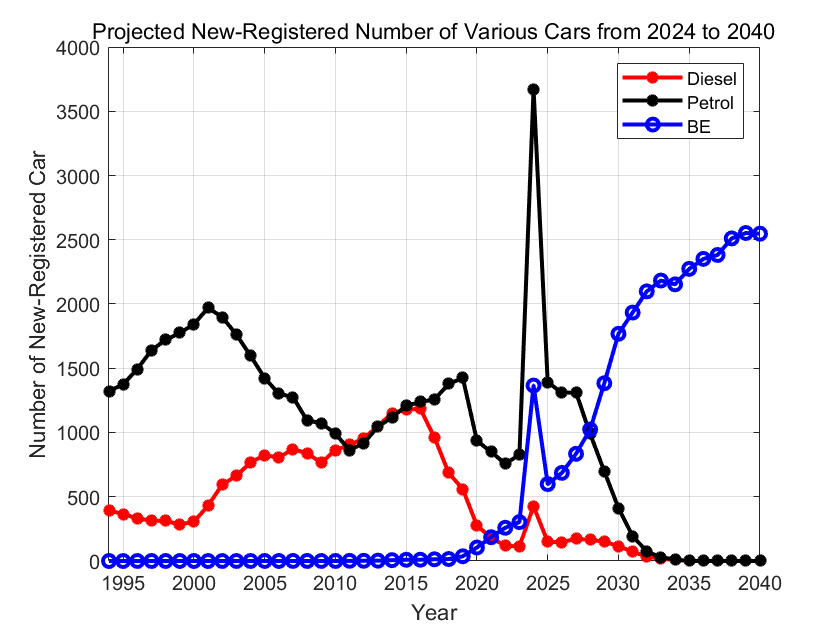

% draw new register number


% new_car_diesel_predict=flipud(diag(flipud(all_car_diesel(years_raw_num+1:end,1:predict_years_num))));
% new_car_petrol_predict=flipud(diag(flipud(all_car_petrol(years_raw_num+1:end,1:predict_years_num))));
% new_car_BE_predict=flipud(diag(flipud(all_car_BE(years_raw_num+1:end,1:predict_years_num))));
% new_LGV_diesel_predict=flipud(diag(flipud(all_LGV_diesel(years_raw_num+1:end,1:predict_years_num))));
% new_LGV_petrol_predict=flipud(diag(flipud(all_LGV_petrol(years_raw_num+1:end,1:predict_years_num))));
% new_LGV_BE_predict=flipud(diag(flipud(all_LGV_BE(years_raw_num+1:end,1:predict_years_num))));
% new_bus_predict=flipud(diag(flipud(all_bus(years_raw_num+1:end,1:predict_years_num))));
% new_HGV_predict=flipud(diag(flipud(all_HGV(years_raw_num+1:end,1:predict_years_num))));
% new_motor_predict=flipud(diag(flipud(all_motor(years_raw_num+1:end,1:predict_years_num))));

new_car_diesel_predict=flipud(diag(flipud(all_car_diesel(:,1:length(years)))));
new_car_petrol_predict=flipud(diag(flipud(all_car_petrol(:,1:length(years)))));
new_car_BE_predict=flipud(diag(flipud(all_car_BE(:,1:length(years)))));
new_LGV_diesel_predict=flipud(diag(flipud(all_LGV_diesel(:,1:length(years)))));
new_LGV_petrol_predict=flipud(diag(flipud(all_LGV_petrol(:,1:length(years)))));
new_LGV_BE_predict=flipud(diag(flipud(all_LGV_BE(:,1:length(years)))));
new_bus_predict=flipud(diag(flipud(all_bus(:,1:length(years)))));
new_HGV_predict=flipud(diag(flipud(all_HGV(:,1:length(years)))));
new_motor_predict=flipud(diag(flipud(all_motor(:,1:length(years)))));

figure(6)
plot(years,new_car_diesel_predict,'-*r','LineWidth',2,"DisplayName",'Diesel')
hold on
plot(years,new_car_petrol_predict,'-*k','LineWidth',2,"DisplayName",'Petrol')
plot(years,new_car_BE_predict,'-ob','LineWidth',2,"DisplayName",'BE')
xlabel('Year');
ylabel('Number of New-Registered Car');
title('Projected New-Registered Number of Various Cars from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

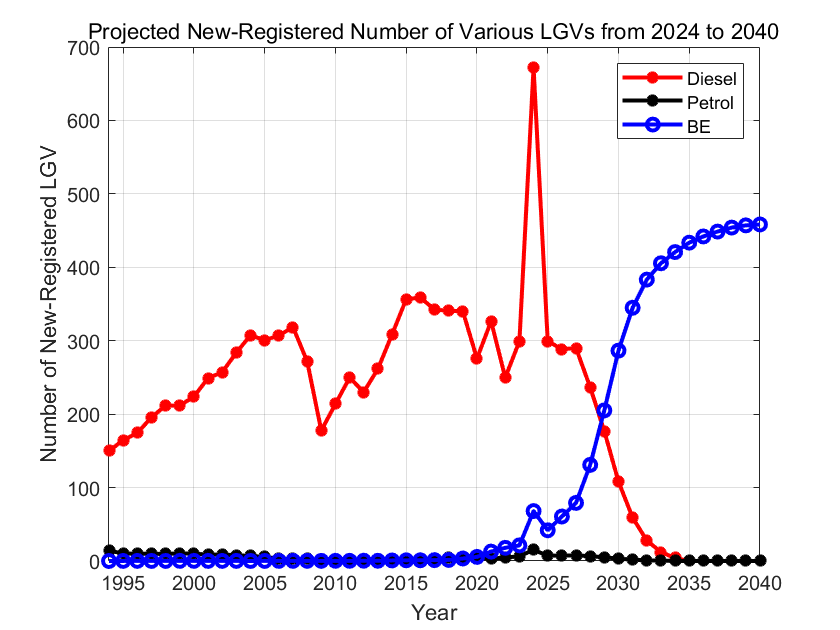


figure(7)
plot(years,new_LGV_diesel_predict,'-*r','LineWidth',2,"DisplayName",'Diesel')
hold on
plot(years,new_LGV_petrol_predict,'-*k','LineWidth',2,"DisplayName",'Petrol')
plot(years,new_LGV_BE_predict,'-ob','LineWidth',2,"DisplayName",'BE')
xlabel('Year');
ylabel('Number of New-Registered LGV');
title('Projected New-Registered Number of Various LGVs from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

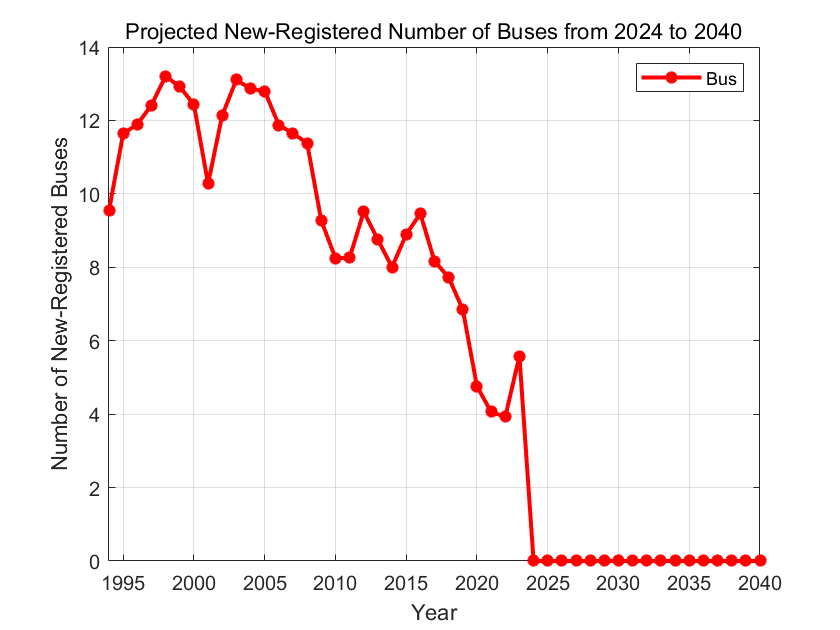


figure(8)
plot(years,new_bus_predict,'-*r','LineWidth',2,"DisplayName",'Bus')
hold on
xlabel('Year');
ylabel('Number of New-Registered Buses');
title('Projected New-Registered Number of Buses from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

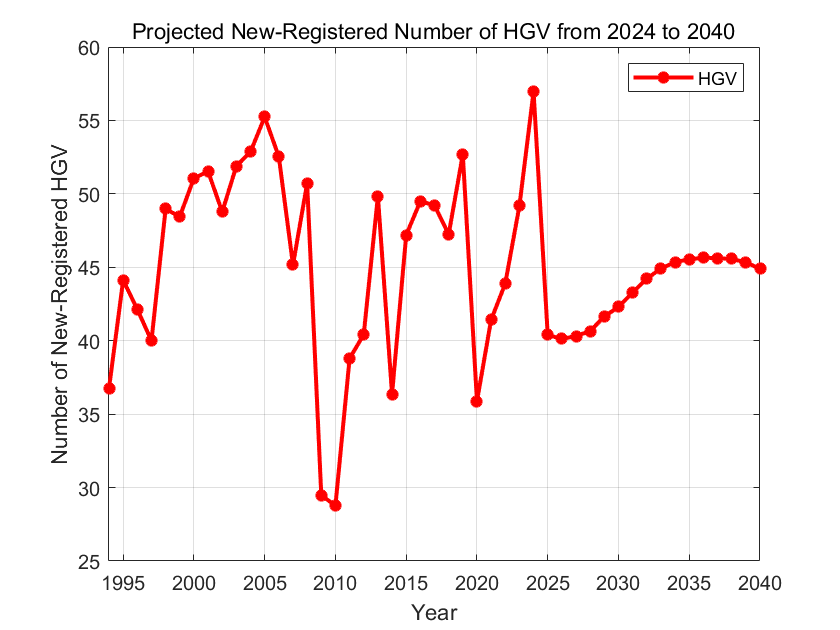


figure(9)
plot(years,new_HGV_predict,'-*r','LineWidth',2,"DisplayName",'HGV')
hold on
xlabel('Year');
ylabel('Number of New-Registered HGV');
title('Projected New-Registered Number of HGV from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;

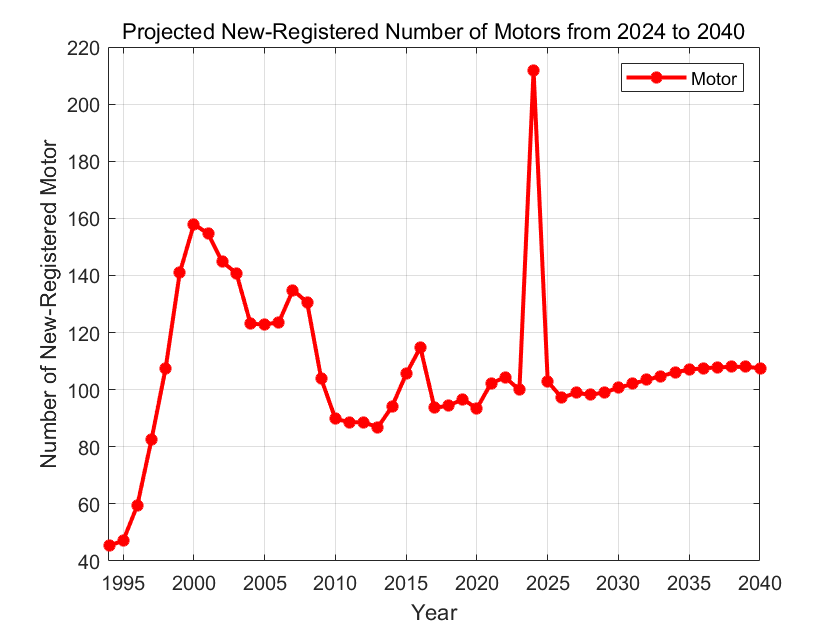


figure(10)
plot(years,new_motor_predict,'-*r','LineWidth',2,"DisplayName",'Motor')
hold on
xlabel('Year');
ylabel('Number of New-Registered Motor');
title('Projected New-Registered Number of Motors from 2024 to 2040')
xlim([1994,2040])
legend show
grid on;
hold off;